%% Setup

rng(1)
pwlregions_init
gcp;  % Initialise parallel pool, partition_regions uses parfor

ans = 

 ProcessPool with properties: 

            Connected: true
           NumWorkers: 6
              Cluster: 

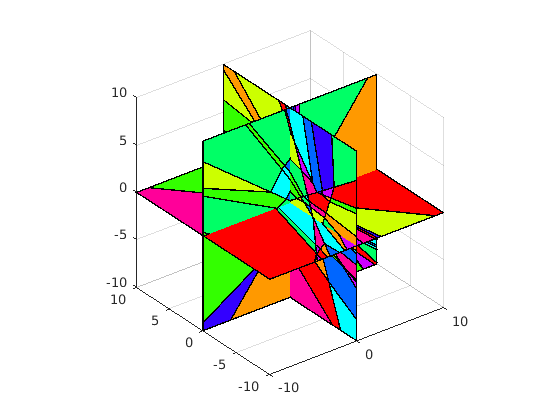

hold off;

## Random net, 3 hidden layers, 3 inputs

n_inputs = 3;
hidden_neurons = [5,5,5];
neurons = [n_inputs ; hidden_neurons(:)];

for i = 1:length(neurons)-1
    random_layers(i) = struct(               ...
        'type', 'dense',                     ...
        'activation', 'relu',                ...
        'W', randn(neurons(i+1),neurons(i)), ...
        'b', randn(neurons(i+1),1)           ...
    );
end
% random_layers(2) = struct('type', 'dense', 'activation', 'relu', 'W', randn(neurons(2),neurons(2)), 'b', randn(neurons(2),1));
% random_layers(3) = struct('type', 'dense', 'activation', 'relu', 'W', randn(neurons(3),neurons(3)), 'b', randn(neurons(3),1));
random_net = PWANetwork(random_layers)

random_net =   PWANetwork with properties:

     layers: [1×4 struct]
    regions: []



disp("The PWA form can be computed for R^3 (the whole input space")

The PWA form can be computed for R^3 (the whole input space


tic
regs3_infinite = random_net.pwa()

Array of 449 polyhedra.


toc

Elapsed time is 3.297926 seconds.


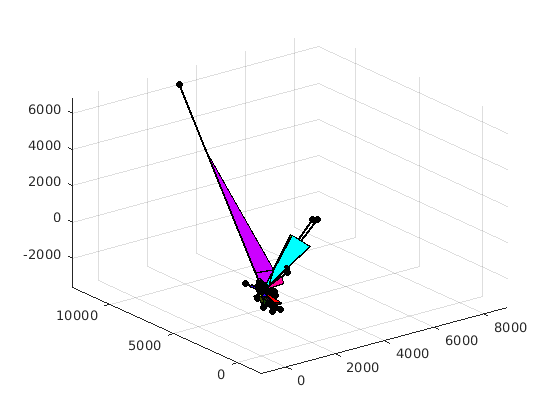

plot(regs3_infinite)

## Finite input space



disp("For best results, a finite input space should be specified.")

For best results, a finite input space should be specified.


disp("This makes plots much easier to understand, and helps with")

This makes plots much easier to understand, and helps with


disp("numerical accuracy. This is fine, because you usually have")

numerical accuracy. This is fine, because you usually have


disp("a finite safe operating space for your system anyways.")

a finite safe operating space for your system anyways.


tic
regs3 = random_net.pwa('input_space', makebox(3,10))

Array of 391 polyhedra.


toc

Elapsed time is 2.152895 seconds.


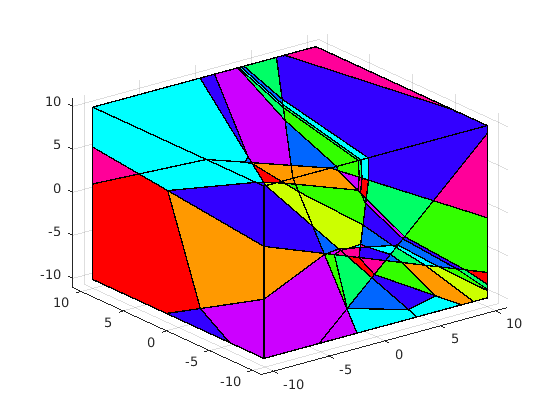


plot(regs3)

## Plotting with transparency


disp("In 3D, some transparency helps to see the inner complexity ")

In 3D, some transparency helps to see the inner complexity 


disp("of this function:")

of this function:


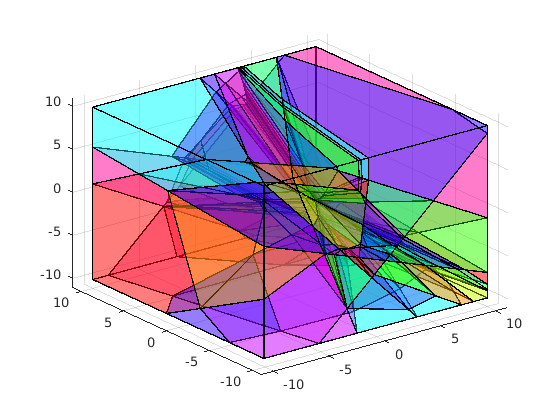


plot(regs3, 'alpha',0.3)

## Lower dim input spaces


xyplane = Polyhedron('He',[0,0,1,0]) & makebox(3,10);
yzplane = Polyhedron('He',[1,0,0,0]) & makebox(3,10);
xzplane = Polyhedron('He',[0,1,0,0]) & makebox(3,10);
disp("It is also possible to find the linear regions on some subspace of the")

It is also possible to find the linear regions on some subspace of the


disp("input. For example, we could find the regions on the xy plane:")

input. For example, we could find the regions on the xy plane:


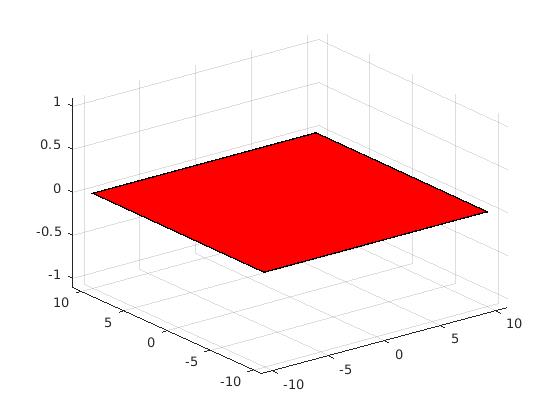


plot(xyplane)


disp("To do this we could take the regions we found earlier and use MPT to")

To do this we could take the regions we found earlier and use MPT to


disp("find the intersection between the 3D regions and the plane. This takes")

find the intersection between the 3D regions and the plane. This takes


disp("a little bit of time, but isn't too bad.")

a little bit of time, but isn't too bad.


tic
restricted = regs3 & xyplane;
toc

Elapsed time is 0.152939 seconds.


% MPT doesn't remove empty intersections, so we do this manually
restricted = restricted(~restricted.isEmptySet)

Array of 83 polyhedra.


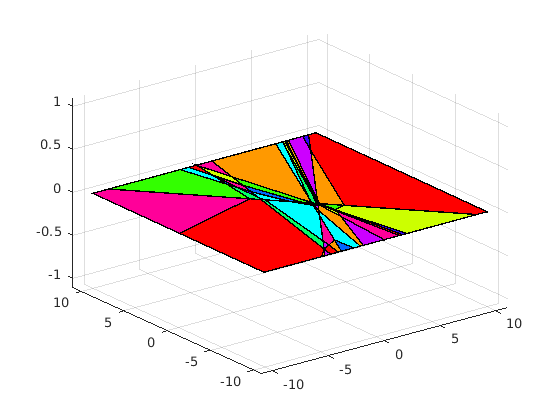

plot(restricted)


disp("However, specifiying the input_space from the start is significantly faster.")

However, specifiying the input_space from the start is significantly faster.


disp("finding the full PWA representation and then intersecting with the subspace.")

finding the full PWA representation and then intersecting with the subspace.


disp("This is because there are exponentially more intersections in high")

This is because there are exponentially more intersections in high


disp("dimensions, and the current algorithm uses these intersections to find the")

dimensions, and the current algorithm uses these intersections to find the


disp("regions.")

regions.


tic
regs3xy = random_net.pwa('input_space', xyplane)

Array of 83 polyhedra.


toc

Elapsed time is 0.791573 seconds.


plot(regs3xy)



disp("You can also ask for the regions with respect to a subset of the inputs.")

You can also ask for the regions with respect to a subset of the inputs.


disp("Finding the regions on xy-plane is equivalent to finding the regions of the")

Finding the regions on xy-plane is equivalent to finding the regions of the


disp("first two inputs, with the third one set to zero. Note that this is an")

first two inputs, with the third one set to zero. Note that this is an


disp("entirely different space, so we need to supply a 2 dimensional input_space.")

entirely different space, so we need to supply a 2 dimensional input_space.


tic
regs2xy = random_net.pwa('inputs', [1,2], 'input_space', makebox(2,10))

Array of 83 polyhedra.


toc

Elapsed time is 0.557334 seconds.


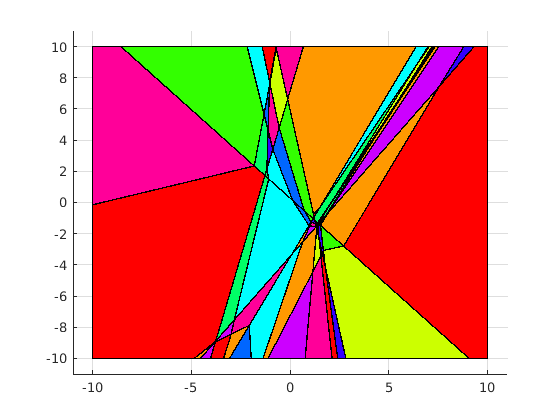

plot(regs2xy)



disp("This is even faster, because computing intersections in higher dimensions")

This is even faster, because computing intersections in higher dimensions


disp("alse has a cost. But retaining the dimensionality is useful for more")

alse has a cost. But retaining the dimensionality is useful for more


disp("complicated visualisations like this:")

complicated visualisations like this:


regs3yz = random_net.pwa('input_space', yzplane);
regs3xz = random_net.pwa('input_space', xzplane);
plot(regs3xy); hold on;
plot(regs3yz);
plot(regs3xz); hold off;
axis equal;

## Outputs


disp("Unfortunately I couldn't get the colours to match (it depends on the order")

Unfortunately I couldn't get the colours to match (it depends on the order


disp("of the regions in the array). It is also possible to visualise the outputs")

of the regions in the array). It is also possible to visualise the outputs


disp("of the network if the input space is 2D. It should be possible to do a kind")

of the network if the input space is 2D. It should be possible to do a kind


disp("of heat map in 3D, but the MPT3 toolbox hasn't implemented this. Here are the")

of heat map in 3D, but the MPT3 toolbox hasn't implemented this. Here are the


disp("two first outputs.")

two first outputs.


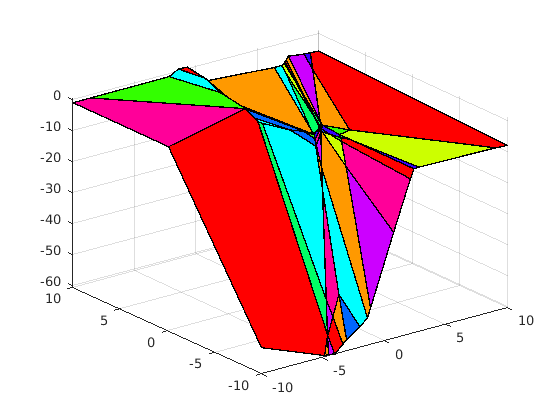


regs2xy.fplot('f1')

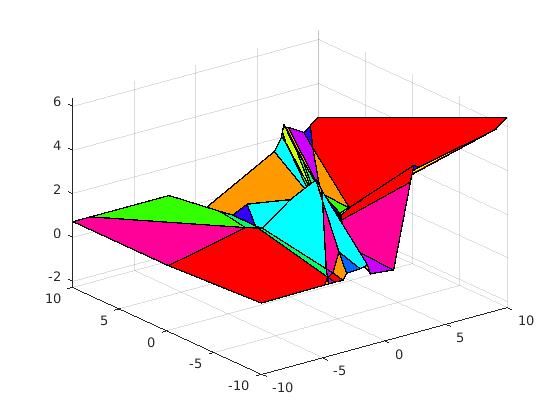

regs2xy.fplot('f2')


disp("Because the last layer of the network has ReLU activation, some of the regions")

Because the last layer of the network has ReLU activation, some of the regions


disp("will be zeroed out. ReLU looks like this:")

will be zeroed out. ReLU looks like this:


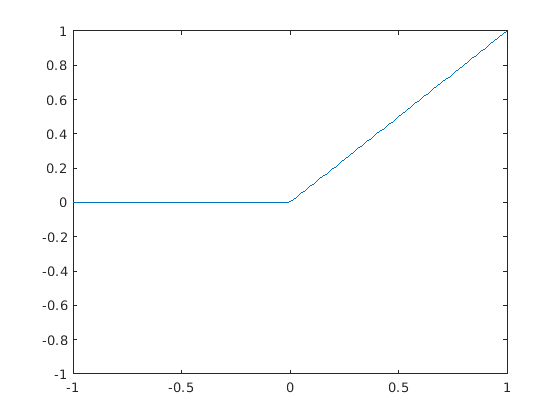

x_ = linspace(-1,1,100);
plot(x_, max(0,x_))
axis([-1,1,-1,1])

## adsf


disp("The sharp corner of ReLU corresponds to the boundaries of the linear regions.")

The sharp corner of ReLU corresponds to the boundaries of the linear regions.


disp("Lets add another layer with no activation and 2 neurons to the network. Then,")

Lets add another layer with no activation and 2 neurons to the network. Then,


disp("lets plot the first outputs over the first two inputs.")

lets plot the first outputs over the first two inputs.


i = length(neurons);
random_layers(i) = struct(                 ...
        'type', 'dense',                     ...
        'activation', 'none',                ...
        'W', randn(2,neurons(i)), ...
        'b', randn(2,1)           ...
    );
net2 = PWANetwork(random_layers);
net2.pwa('inputs', [1,2], 'input_space', makebox(2,10))

Array of 83 polyhedra.


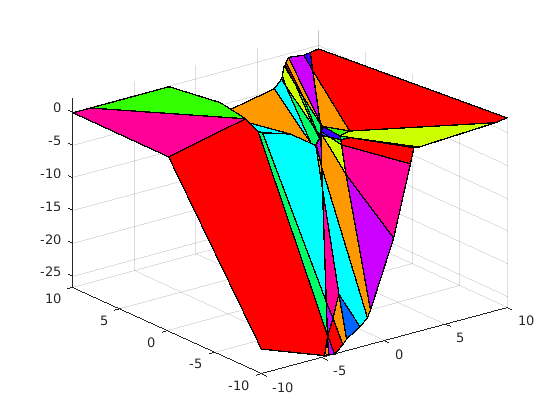

% Instead of using fplot directly, the PWANetwork class has a convenience function
% for plotting outputs (It uses the last computed linear regions for this)
net2.plot_output(1)

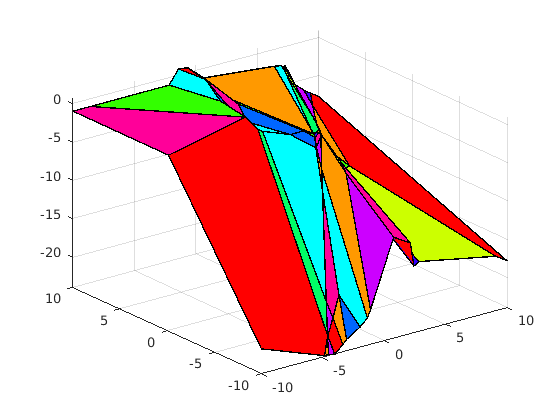

net2.plot_output(2)


disp("Adding a layer with no activation doesn't change the linear regions")

Adding a layer with no activation doesn't change the linear regions


disp("at all, only the output. ")

at all, only the output. 




disp("We can only really visualise 2D and 3D regions, so these techniques cover")

We can only really visualise 2D and 3D regions, so these techniques cover


disp("pretty much all the kinds of plots that you can make with this.")

pretty much all the kinds of plots that you can make with this.
